# レーティング変換の例

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む

load sample_ratingConv.mat

レーティング最小値と最大値の確認

[min(RateDiff) max(RateDiff)]

ans =   -18.3681   18.9566


### 1試合に対しそれぞれのチームから見た結果と予測に基づきモデルを導出する

レーティング差と実勝敗それぞれ対戦相手から見た値を追加する．

RateDiff_org=RateDiff;
RateDiff=[RateDiff_org;-RateDiff_org];

ActualWin_org=ActualWin;
ActualWin=[ActualWin_org;1-ActualWin_org];

実際の勝敗ごとにレーティングを集計

edges=-20:20;
bins=movmean(edges,2,'Endpoints','discard');
winCounts=histcounts( RateDiff(ActualWin==1),edges);
loseCounts=histcounts( RateDiff(ActualWin==0),edges);
figure
subplot(2,1,1)
bar(bins,[winCounts;loseCounts],'stacked','BarWidth',1,'EdgeColor','w','FaceAlpha',0.5)
grid on;
set(gca,'FontName','メイリオ','FontSize',12)
ylabel('試合数')
set(gca,'XTickLabel',[])
legend({'勝ち','負け'},'location','best')

subplot(2,1,2)
bar(bins,[winCounts;loseCounts]./(winCounts+loseCounts), ...
    'stacked','BarWidth',1,'EdgeColor','w','FaceAlpha',0.5)
grid on;
set(gca,'FontName','arial','FontSize',12)
ylabel('割合')
xlabel('レーティング差')

レーティング差と勝率の対応を3パラメータロジスティックモデルとして求める

(ここではパラメータcはあらかじめ決めた値としている)

c=0.05;
mdl2=glmfit(RateDiff, c+(1-2*c)*ActualWin,'binomial','logit')

mdl2 =     0.0000
    0.1018


glmval(mdl2,0,'logit')

ans = 0.5000

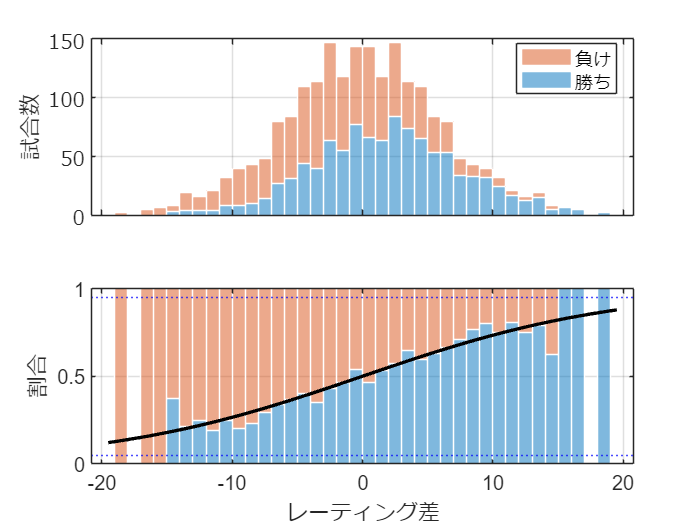

subplot(2,1,2)
hold on
plot(bins, glmval(mdl2,bins,'logit'),'k-','LineWidth',2);
yline(c, 'b:');yline(1-c,'b:')
exportgraphics(gcf,'fig_ratingTransformationExample03.pdf');